% Import process data
data = z10

data =

Time domain data set with 340 samples.
Sample time: 0.05 seconds              
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       Unit (if specified)       
   u1                                  
                                       


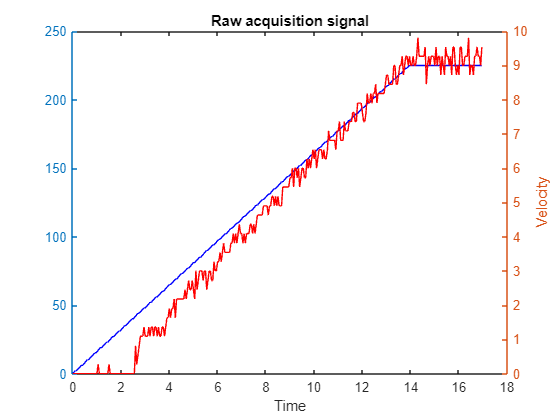

% Plot raw signal
clear xlabel ylabel title legend

t = 0:.05:.05*(size(data.y,1)-1); % time vector

figure
yyaxis left
plot(t, data.u, 'b-')

yyaxis right
plot(t, data.y, 'r-')
ylabel('Velocity')

xlabel('Time')
title('Raw acquisition signal')

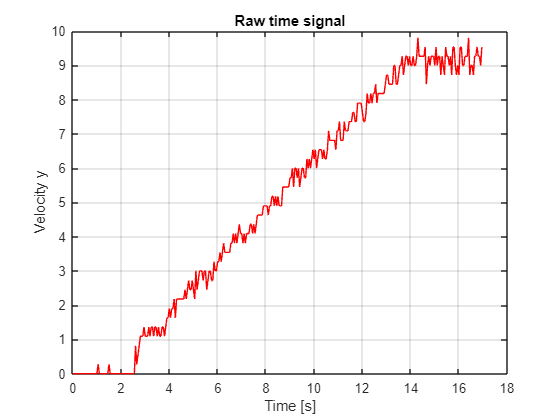

%% 1. Khởi tạo tham số lấy mẫu và tín hiệu gốc

Ts   = 0.05;           % chu kỳ lấy mẫu [s]
Fs   = 1/Ts;           % tần số lấy mẫu [Hz]
Fnyq = Fs/2;           % tần số Nyquist [Hz]

y_raw = data.y(:);     % tín hiệu vận tốc (dạng cột)
N     = numel(y_raw);  % số mẫu
t     = (0:N-1)*Ts;    % trục thời gian

% Vẽ tín hiệu gốc trong miền thời gian
figure; clf
plot(t, y_raw, 'r-');
xlabel('Time [s]');
ylabel('Velocity y');
title('Raw time signal');
grid on;

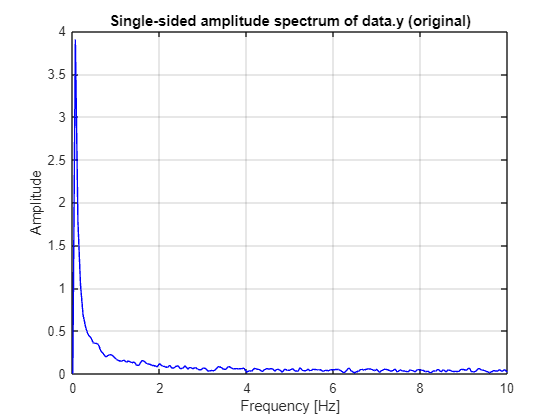



%% 2. FFT và phổ biên độ một phía (dùng bản đã bỏ DC cho rõ phổ)

y_fft = y_raw - mean(y_raw);    % chỉ dùng để phân tích phổ

Y = fft(y_fft);

P2 = abs(Y)/N;                  % phổ hai phía (chuẩn hóa theo N)
P1 = P2(1:floor(N/2)+1);        % phổ một phía 0..Fnyq
if numel(P1) > 2
    P1(2:end-1) = 2*P1(2:end-1);
end

f = Fs*(0:floor(N/2))/N;        % trục tần số [Hz]

figure; clf
plot(f, P1, 'b-');
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('Single-sided amplitude spectrum of data.y (original)');
grid on;
xlim([0 Fnyq]);

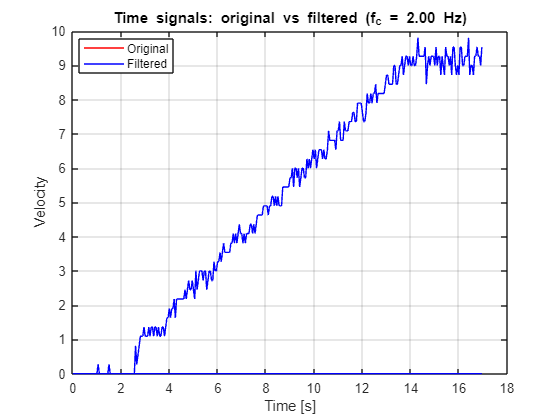



%% 3. Thiết kế bộ lọc thông thấp trong miền tần số

% Chọn tần số cắt (có thể chỉnh lại sau khi xem phổ)
fc = 2;                          % [Hz]

% Trục tần số đầy đủ cho N điểm FFT: -Fs/2 .. Fs/2-Fs/N
f_full = (-N/2:N/2-1) * (Fs/N);

% FFT của tín hiệu gốc (KHÔNG trừ mean để giữ ramp/step)
Y_full  = fft(y_raw);
Y_shift = fftshift(Y_full);      % dịch zero frequency về giữa

% Mặt nạ bộ lọc thông thấp lý tưởng: giữ |f| <= fc
H = ones(size(f_full));
H(abs(f_full) > fc) = 0;

% Áp dụng bộ lọc
Y_filt_shift = Y_shift .* H;

% Dịch ngược lại và IFFT về miền thời gian
Y_filt = ifftshift(Y_filt_shift);
y_filt = ifft(Y_filt, 'symmetric');   % tín hiệu sau lọc (thực)


%% 4. So sánh tín hiệu thời gian trước và sau lọc

figure; clf
plot(t, y_raw, 'r-', t, y_filt, 'b-');
xlabel('Time [s]');
ylabel('Velocity');
title(sprintf('Time signals: original vs filtered (f_c = %.2f Hz)', fc));
grid on;
legend('Original','Filtered','Location','best');

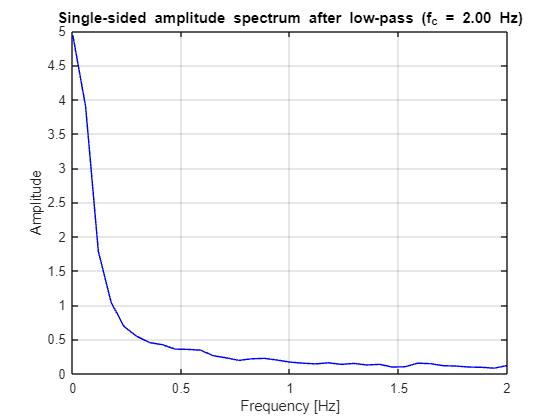



%% 5. Phổ biên độ một phía sau khi lọc

Y_lp = fft(y_filt);

P2_lp = abs(Y_lp)/N;
P1_lp = P2_lp(1:floor(N/2)+1);
if numel(P1_lp) > 2
    P1_lp(2:end-1) = 2*P1_lp(2:end-1);
end

f_lp = Fs*(0:floor(N/2))/N;

figure; clf
plot(f_lp, P1_lp, 'b-');
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title(sprintf('Single-sided amplitude spectrum after low-pass (f_c = %.2f Hz)', fc));
grid on;
xlim([0 fc]);   % zoom vùng tần số thấp

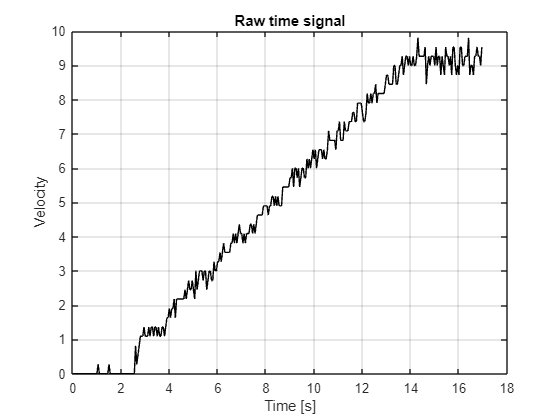

%% 1. Tham số lấy mẫu và tín hiệu gốc

Ts   = 0.05;                 % chu kỳ lấy mẫu [s]
Fs   = 1/Ts;                  % tần số lấy mẫu [Hz]
Fnyq = Fs/2;                  % tần số Nyquist

y_raw = data.y(:);            % tín hiệu vận tốc
N     = numel(y_raw);
t     = (0:N-1)*Ts;

figure; clf
plot(t, y_raw, 'k-');
xlabel('Time [s]');
ylabel('Velocity');
title('Raw time signal');
grid on;

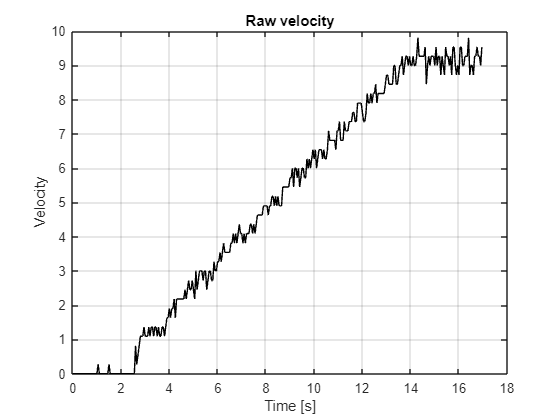

%% 1. Tham số lấy mẫu và tín hiệu gốc

Ts   = 0.05;                 % chu kỳ lấy mẫu [s]
Fs   = 1/Ts;                  % tần số lấy mẫu [Hz]
Fnyq = Fs/2;                  % tần số Nyquist

y_raw = data.y(:);            % tín hiệu vận tốc
N     = numel(y_raw);
t     = (0:N-1)*Ts;


%% 2. Thiết kế và áp dụng bộ lọc Butterworth + Moving Average (offline)

% --- Butterworth low-pass ---
fc_butt    = 2;               % [Hz] tần số cắt
order_butt = 20;               % bậc lọc

Wn = fc_butt / Fnyq;          % tần số cắt chuẩn hóa (0..1)
[b,a] = butter(order_butt, Wn, 'low');

% filtfilt: lọc tiến+lùi, không trễ pha (offline)
y_butt = filtfilt(b, a, y_raw);

% --- Moving average (cửa sổ M mẫu) ---
M   = 20;                      % số mẫu trong cửa sổ
b_ma = (1/M)*ones(1,M);
a_ma = 1;

y_ma = filtfilt(b_ma, a_ma, y_raw);   % cũng dùng filtfilt cho mượt


%% 3. Hình riêng: tín hiệu gốc

figure; clf
plot(t, y_raw, 'k-');
xlabel('Time [s]');
ylabel('Velocity');
title('Raw velocity');
grid on;

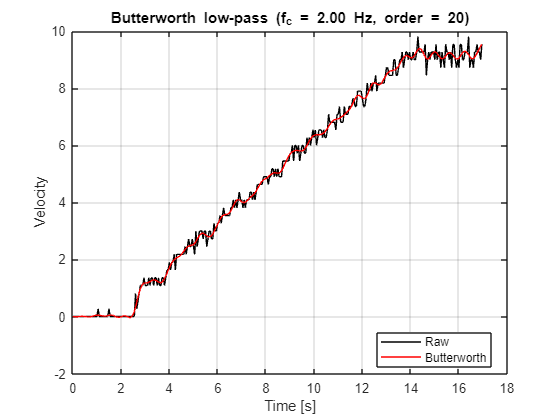



%% 4. Hình riêng: gốc + Butterworth

figure; clf
plot(t, y_raw,  'k-', 'DisplayName','Raw'); hold on;
plot(t, y_butt, 'r-', 'DisplayName','Butterworth');
xlabel('Time [s]');
ylabel('Velocity');
title(sprintf('Butterworth low-pass (f_c = %.2f Hz, order = %d)', fc_butt, order_butt));
grid on;
legend('Location','best');

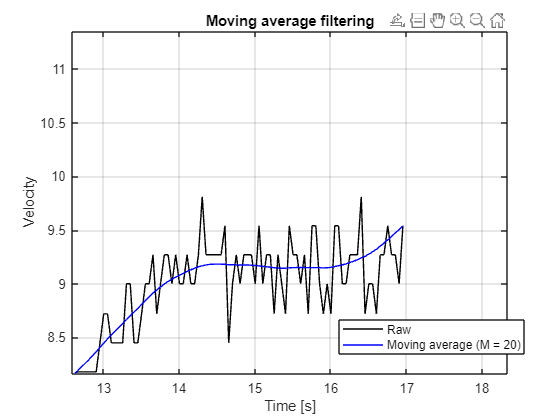



%% 5. Hình riêng: gốc + Moving Average

figure; clf
plot(t, y_raw, 'k-', 'DisplayName','Raw'); hold on;
plot(t, y_ma,   'b-', 'DisplayName',sprintf('Moving average (M = %d)', M));
xlabel('Time [s]');
ylabel('Velocity');
title('Moving average filtering');
grid on;
legend('Location','best');

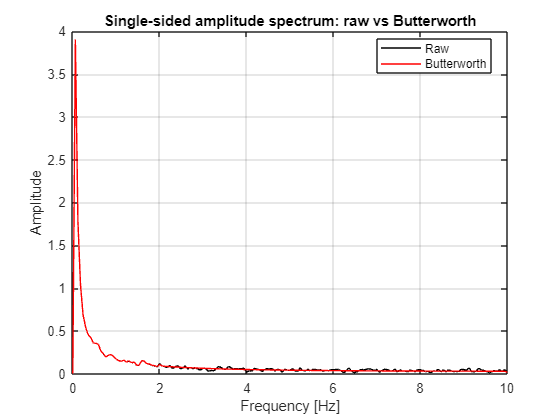




%% 5. So sánh phổ sau khi lọc (Butterworth)

Y_raw  = fft(y_raw - mean(y_raw));
Y_bf   = fft(y_butt - mean(y_butt));

P2_raw = abs(Y_raw)/N;
P1_raw = P2_raw(1:floor(N/2)+1);
if numel(P1_raw) > 2, P1_raw(2:end-1) = 2*P1_raw(2:end-1); end

P2_bf = abs(Y_bf)/N;
P1_bf = P2_bf(1:floor(N/2)+1);
if numel(P1_bf) > 2, P1_bf(2:end-1) = 2*P1_bf(2:end-1); end

f = Fs*(0:floor(N/2))/N;

figure; clf
plot(f, P1_raw, 'k-', f, P1_bf, 'r-');
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('Single-sided amplitude spectrum: raw vs Butterworth');
grid on;
xlim([0 Fnyq]);
legend('Raw','Butterworth','Location','best');